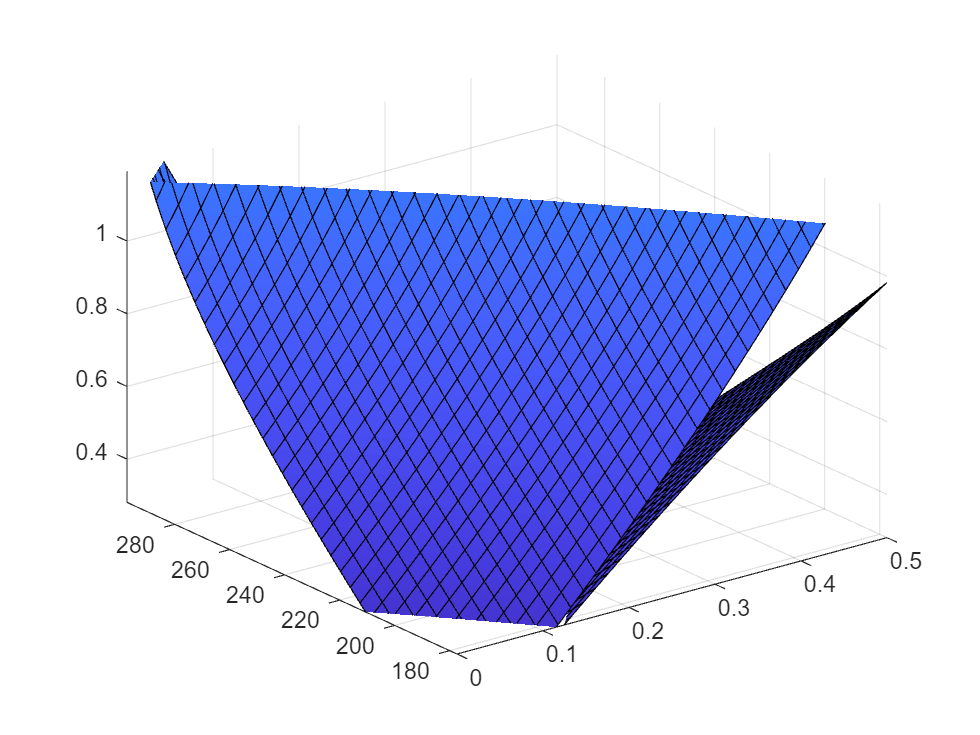

format long
clear figure
hold off

% constants
% syms l1 l2 a
l1 = 120;
l2 = 177.353;
a = 322.815;
thetal = 16.1/180*pi;
thetau = 68.28/180*pi;
% inputs
syms alpha1 alpha2 h
% l2 <= h <= l1+l2
% outputs
syms theta1 theta2 theta3 theta4
syms B1 B2 B3 B4

B1 = (h-a/2*sin(alpha1)-l2*cos(alpha1))/l1;
B3 = (h+a/2*sin(alpha1)-l2*cos(alpha1))/l1;
theta1 = abs(alpha1-asin(B1));
theta3 = abs(alpha1+asin(B3));

fsurf(theta1)
hold on
fsurf(theta3);
%xlim([0 pi/2]);
%ylim([l2 l1+l2]);
zlim([thetal thetau]);

% zoom in
xlim([0 0.5]);
ylim([l2 l1+l2]);

x = linspace(0,0.5,100);
y = linspace(l2,l1+l2,100);
[xM,yM] = ndgrid(x,y);
theta1M = arrayfun(@(x,y) eval(subs(theta1,[alpha1,h],[x,y])),xM,yM);
theta3M = arrayfun(@(x,y) eval(subs(theta3,[alpha1,h],[x,y])),xM,yM);
% overlapping region is within all constraints, thus being workspace
w = (theta1M<=thetau) & (theta1M>=thetal) & (theta3M<=thetau) & (theta3M>=thetal);
mesh(xM,yM,w);

figure;
contour(xM,yM,w);

Unrecognized function or variable 'xM'.